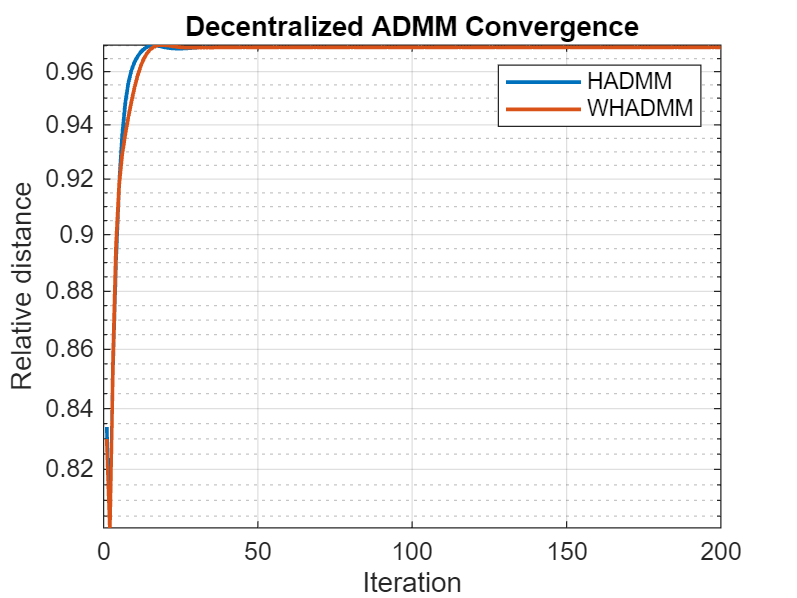

% decentralized_admm_whadmm.m
clear; rng(1);

%% parameters
N = 50;       % number of nodes
l = 3;        % dimension of local variable xi
p_edge = 0.06; % probability of edge (Erdos-Renyi)
rho = 1.0;    % ADMM penalty
maxIter = 200;

%% create random graph (undirected)
Aadj = rand(N) < p_edge;
Aadj = triu(Aadj,1);
Aadj = Aadj + Aadj';
[iList,jList] = find(triu(Aadj,1));
M = numel(iList); % number of edges

E = cell(M,1);
for e=1:M
    E{e} = [iList(e), jList(e)];
end

%% form A, B
T = sum(cellfun(@numel,E));
rows = []; cols = []; vals = [];
rowsB = []; colsB = []; valsB = [];
t = 0;
for e=1:M
    nodes = E{e};
    for ni = nodes
        t = t + 1;
        for dim=1:l
            rows(end+1) = (t-1)*l + dim;
            cols(end+1) = (ni-1)*l + dim;
            vals(end+1) = 1;
            rowsB(end+1) = (t-1)*l + dim;
            colsB(end+1) = (e-1)*l + dim;
            valsB(end+1) = -1;
        end
    end
end
A_big = sparse(rows, cols, vals, T*l, N*l);
B_big = sparse(rowsB, colsB, valsB, T*l, M*l);

rowsC = []; colsC = []; valsC = [];
for e=1:M
    nodes = E{e};
    for ni = nodes
        for dim=1:l
            rowsC(end+1) = (ni-1)*l + dim;
            colsC(end+1) = (e-1)*l + dim;
            valsC(end+1) = 1;
        end
    end
end
C_big = sparse(rowsC, colsC, valsC);

% degrees
D_big = kron(spdiags(sum(C_big~=0,2),0,N*l,N*l), speye(1));
deg_edge = cellfun(@numel,E);
E_big = kron(spdiags(deg_edge,0,M,M), speye(l));

%% quadratic local objectives
qs = 0.5 + rand(N,1);
Bvec = randn(N*l,1);
Q_big = kron(spdiags(qs,0,N,N), speye(l));
x_star = (Q_big + 1e-9*speye(N*l)) \ (Q_big * Bvec);

%% preconditioner S
G = A_big*A_big' + B_big*B_big';
gdiag = full(diag(G));
S_diag = 1 ./ sqrt(gdiag + 1e-8);
S_mat = spdiags(S_diag,0,T*l,T*l);

idx_node = @(i) ((i-1)*l+1):(i*l);
idx_edge = @(e) ((e-1)*l+1):(e*l);

%% run HADMM and WHADMM
results = struct();

for method = 1:2
    if method==1, S_use = speye(T*l); tag = 'HADMM'; else, S_use = S_mat; tag = 'WHADMM'; end

    A_w = S_use * A_big;
    B_w = S_use * B_big;

    % constraint bookkeeping
    t = 0; constr_node = zeros(T,1); constr_edge = zeros(T,1);
    for e=1:M
        nodes = E{e};
        for ni = nodes
            t = t + 1; constr_node(t) = ni; constr_edge(t) = e;
        end
    end
    deg_node_counts = accumarray(constr_node, 1, [N,1]);
    deg_edge_counts = accumarray(constr_edge, 1, [M,1]);
    D_hat = kron(spdiags(deg_node_counts,0,N,N), speye(l));
    E_hat = kron(spdiags(deg_edge_counts,0,M,M), speye(l));

    % build C_hat
    C_hat = sparse(N*l, M*l);
    for e=1:M
        nodes = E{e};
        for ni=nodes
            C_hat(idx_node(ni), idx_edge(e)) = C_hat(idx_node(ni), idx_edge(e)) + eye(l);
        end
    end

    % initialize
    x = randn(N*l,1);
    y = zeros(N*l,1);
    inv_node = cell(N,1);
    for i=1:N
        di = deg_node_counts(i);
        inv_node{i} = inv(qs(i)*eye(l) + rho*di*eye(l));
    end

    rel_err = zeros(maxIter,1);
    for k=1:maxIter
        v = C_hat * ( (E_hat) \ ( C_hat' * x ) );
        x_new = zeros(N*l,1);
        for i=1:N
            yi = y(idx_node(i)); v_i = v(idx_node(i));
            rhs = qs(i)*Bvec(idx_node(i)) - (yi - rho * v_i);
            x_new(idx_node(i)) = inv_node{i} * rhs;
        end
        v_new = C_hat * ( (E_hat) \ ( C_hat' * x_new ) );
        y = y + rho * (D_hat * x_new - v_new);
        x = x_new;
        rel_err(k) = norm(x - x_star) / (norm(x_star)+1e-12);
    end
    results.(tag).rel_err = rel_err;
end

%% plot
figure;
semilogy(1:maxIter, results.HADMM.rel_err, 'LineWidth', 1.5); hold on;
semilogy(1:maxIter, results.WHADMM.rel_err, 'LineWidth', 1.5);
xlabel('Iteration'); ylabel('Relative distance');
legend('HADMM','WHADMM'); grid on;
title('Decentralized ADMM Convergence');